# Write Table to XML File

Create a table of data, then write it to an XML file. Customize how `writetable` writes table data to the XML file by specifying additional name-value arguments.

Create a table of data.

InsectSpecies = {'Monarch Butterfly';'Seven-spot Ladybird';'Orchid Mantis'; ...
    'American Bumblebee';'Blue Dasher Dragonfly'};
InsectOrder = {'Lepidoptera';'Coleoptera';'Mantodea';'Hymenoptera';'Odonata'};
InsectFamily = {'Nymphalidae';'Coccinellidae';'Hymenopodidae'; ...
    'Apidae';'Libellulidae'};
PredatoryInsect = logical([0;1;1;0;1]); 

T = table(InsectOrder,InsectFamily,PredatoryInsect);
T.Properties.RowNames = InsectSpecies;
head(T,5)

Write the table `T` to an XML file called `InsectCollection.xml`. Specify `'WriteRowNames'` as `true` to write the names of the table rows. The row names appear as fields belonging to the `Row` element node in the output XML file.

Customize the node names in the XML file by specifying `'Insect'` as the value of `'RowNodeName'`.

writetable(T,'InsectCollection.xml',"WriteRowNames",false,"RowNodeName","Insect")

Display the contents of the file `InsectCollection.xml`.

type InsectCollection.xml

If you do not specify `WriteRowNames` as `true`, `writetable` skips writing the table row names to the file.

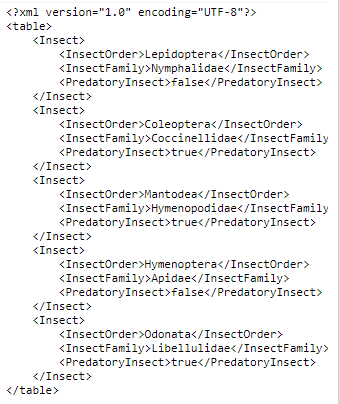

*Copyright 2020 The MathWorks, Inc.*